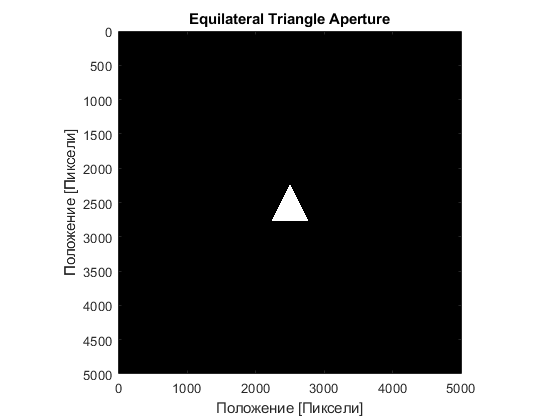

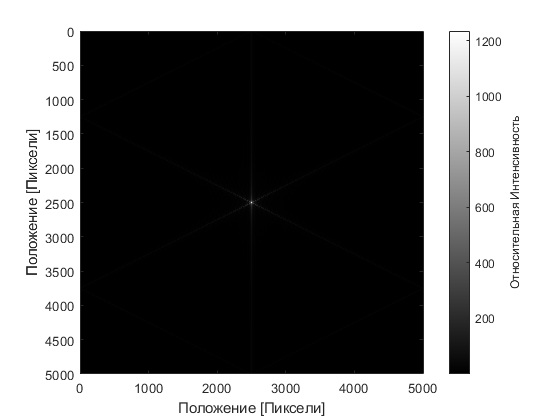

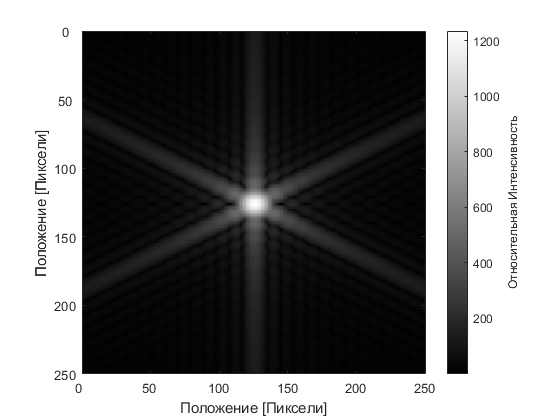

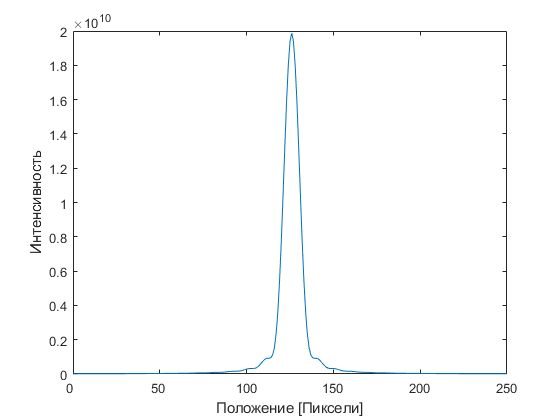

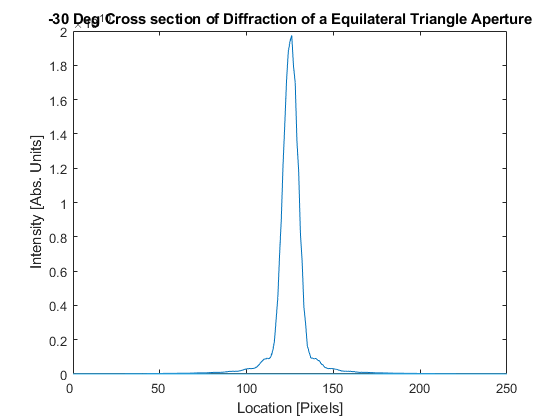

% Визуализация дифракции дальнего поля от различных апертур
% Этот скрипт предназначен для вывода визуализации дифракции в дальнем поле
% различных апертур и предоставления графиков интенсивности и расстояния вдоль плоскости xy.
% Принимает пользовательский ввод для определения диафрагмы.
% Апертуры: "Квадрат", "Одинарная щель"
% "Круг", "Прямоугольный треугольник", "Равносторонний треугольник".


%FarFieldDiffractionVis_final('Square');
%FarFieldDiffractionVis_final('SingleSlit');
%FarFieldDiffractionVis_final('Circular');
FarFieldDiffractionVis_final('EquilateralTriangle');

function FarFieldDiffractionVis_final(aperture) %Эта функция создает диафрагму на основе входных данных пользователя.
% Раздел константы
% Определяем апертуру
apl=5000;% Размер поля диафрагмы Примеры: 5000
sql=550; % Длина квадрата Примеры: 500
slitW=200; % Ширина щели Примеры: 200
slitH=2500;% Высота щели Примеры: 2500
%slit2w=175; % Ширина двойной щели Примеры: 175
%slit2H=2500; % Высота двойной щели Примеры: 2500
%slit2space=500; % Расстояние между центрами двойной щели Примеры: 500
rad=275; % Радиус круга Примеры: 275
%tri=1500; % Длина стороны для прямоугольного треугольника Примеры: 1500
eqtri=680; % Длина стороны равностороннего треугольника Примеры: 900
%chickenspace=250; % Расстояние между черными линиями Примеры: 250
%chickensquare=150; % Ширина черных линий Примеры: 150
ap=zeros(apl); % Определение фактической плоскости диафрагмы

% Выбор секции диафрагмы
if strcmp(aperture,'Square')==1 % Выбор типа диафрагмы, вычисление матрицы, определяющую каждую диафрагму
    a=0.25; % коэффициент регулировки интенсивности
    ttle='Square Aperture'; % Определение названия для будущих графиков
    % Квадрат
    for ijk=round(1+apl/2-sql/2):round(1+apl/2+sql/2) % Вертикальная часть
        for lmn=round(1+apl/2-sql/2):round(1+apl/2+sql/2) % Горизонтальная часть
            ap(ijk,lmn)=1;
        end
    end
    
elseif strcmp(aperture,'SingleSlit')==1
    a=0.3; % коэффициент регулировки интенсивности
    ttle='Single Slit Aperture'; % Определение названия для будущих графиков
    % Щель 
    for ijk=round(1+apl/2-slitH/2):round(1+apl/2+slitH/2) % Вертикальная часть
        for lmn=round(1+apl/2-slitW/2):round(1+apl/2+slitW/2) % Горизонтальная часть
             ap(ijk,lmn)=1;
        end
    end
 
elseif strcmp(aperture,'Circular')==1
    a=0.3; % коэффициент регулировки интенсивности
    ttle='Circular Aperture'; % Определение названия будущих графиков
    % Круглое отверстие
    xcenter=apl/2; % Вычисляет центральную точку для оси x
    ycenter=apl/2; % Вычисляет центральную точку для оси y
    rad2=rad^2; % Квадрат радиуса
    for ijk=1:apl
        for abc=1:apl
            dx=ijk-xcenter; % Определение положения x от центра
            dy=abc-ycenter; % Определение положения y от центра
            x2=dx^2; 
            y2=dy^2; 
            ap(ijk,abc)=x2+y2<=rad2; % Вычисляет, находится ли точка в радиусе окружности 
        end
    end
      
elseif strcmp(aperture,'EquilateralTriangle')==1
    a=0.3; % коэффициент регулировки интенсивности
    ttle='Equilateral Triangle Aperture'; 
    % Равносторонний треугольник
    addr=0; % Определяет сумматор для последовательной работы через треугольник.
    for ijk=round(1+(apl/2)-(eqtri/2)./sqrt(3)):round(1+(apl/2)+(eqtri/2)./sqrt(3)) % Вертикальная часть
        for lmn=round(1+(apl/2)-addr/2):round(1+(apl/2)+addr/2) % Горизонтальная часть
        ap(ijk,lmn)=1;
        end
        addr= addr+1;
    end    
   
else
    % Ошибки
   disp('Error 404: Aperture not found. Please input a valid aperture name.') % Отображает сообщение об ошибке, если задана недопустимая диафрагма. Отображает имена правильных апертур
   disp('Valid aperture names are: ''Square'', ''SingleSlit'', ''DoubleSlit'', ''Circular''')
   disp('''RightTriangle'', ''EquilateralTriangle'', and ''ChickenWire''.')
    
   return % Код перестанет выполняться, если он достигнет этой точки
end



% Графики 

% График апертуры
figure(1) 
imagesc(ap) % Изображнение поля диафрагмы
colormap gray % Цвет графика поля диафрагмы
axis equal % Масштаб отображения оси
axis([0 apl 0 apl]) % Ограничения по оси для размера поля диафрагмы
xlabel('Положение [Пиксели]'); % Название оси x
ylabel('Положение [Пиксели]'); % Название оси y
title(ttle); % Название графика 

% Преобразование фурье для апертуры
F=fft2 (ap); % Fourier transformation for aperture
Fc=fftshift(F); % Центрирует преобразование фурье, смещая частоту 0 в центр
I=abs(Fc).^2; % Считаем интенсивность
Ia=(I).^(a); % Считаем скорректированную интенсивность


figure(2) 
imagesc(Ia) % График изображения интенсивности дифракции
colormap gray % Цвет
axis equal % Масштаб отображения оси
axis([0 apl 0 apl]) % Ограничения по оси для размера поля диафрагмы
c=colorbar; % Добавляет цветовую панель и определяет ее как переменную, чтобы позже добавить заголовок цветовой панели
c.Label.String='Относительная Интенсивность'; % Добавляем цветовую панель
%title ([ttle]);% Добавляем заголовок
xlabel('Положение [Пиксели]');% Название оси x
ylabel('Положение [Пиксели]');% Название оси y

figure(3) 
imagesc(Ia) % % График изображения интенсивности дифракции
colormap gray % Цвет графика поля диафргамы
axis equal % Масштаб отображжения оси
axis([2375 2625 2375 2625]) % Ограничения по оси
c=colorbar;% Добавляет цветовую панель и определяет ее как переменную, чтобы позже добавить заголовок цветовой панели
c.Label.String='Относительная Интенсивность';% Цветная панель
%title ([ttle]) % Название графика
set(gca,'XTick',2375:50:2625)% Тики по оси x
set(gca,'XTickLabel',0:50:250)% Изменение тиков
set(gca,'YTick',2375:50:2625)% Тики по оси y
set(gca,'YTickLabel',0:50:250)% Изменение таков
xlabel('Положение [Пиксели]');% Навзвание оси x 
ylabel('Положение [Пиксели]');% Навзвание оси y


figure(4) 
plot(I(:,2500)); % Постройте график вертикального поперечного сечения интенсивности по отношению к положению
xlim([2375 2625]) % Устанавливает пределы для центра 250 пикселей в вертикальном поперечном сечении
set(gca,'XTick',2375:50:2625)% Тики оси x
set(gca,'XTickLabel',0:50:250)% Изменение тиков
%title(['Vertical Cross section of Diffraction of a ' ttle]) % Название графика
xlabel('Положение [Пиксели]');% Название оси x
ylabel('Интенсивность');% Название оси y


figure(5) 
plot(I(2500,:));% Постройте график горизонтального поперечного сечения интенсивности по отношению к положению
xlim([2375 2625])% Устанавливает пределы для центра 250 пикселей в горизонтальном поперечном сечении
set(gca,'XTick',2375:50:2625) % Тики оси x
set(gca,'XTickLabel',0:50:250) % Изменение тиков
%title(['Horizontal Cross section of Diffraction of a ' ttle])% Название графика
xlabel('Location [Pixels]');% Название оси x
ylabel('Intensity [Abs. Units]');% Название оси y


if strcmp(aperture,'EquilateralTriangle')==1
%% Секция тестирования на 30 градусов
figure(7);
degpos=zeros(8000);
for ijk=1:5000 % Этот цикл for создает 1D массив значений по оси 30 градусов от x.
    tmp=1250+ijk.*sind(30);
    degpos(ijk)=I(round(tmp),ijk);
end
plot(degpos);
xlim([2375 2625])% Устанавливает пределы для центра 250 пикселей в горизонтальном поперечном сечении
set(gca,'XTick',2375:50:2625) % Тики оси x
set(gca,'XTickLabel',0:50:250) % Изменение тиков
title(['30 Deg Cross section of Diffraction of a ' ttle])% Название графика
xlabel('Location [Pixels]');% Название оси x
ylabel('Intensity [Abs. Units]');% Название оси y

figure(8);
degpos(8000);
for ijk=1:5000
    tmp=3750+ijk.*sind(-30);
    degpos(ijk)=I(round(tmp),ijk);
end
plot(degpos)
xlim([2375 2625])% Устанавливает пределы для центра 250 пикселей в горизонтальном поперечном сечении
set(gca,'XTick',2375:50:2625) % Тики оси x
set(gca,'XTickLabel',0:50:250) % Изменение тиков
title(['-30 Deg Cross section of Diffraction of a ' ttle])% Название графика
xlabel('Location [Pixels]');% Название оси x
ylabel('Intensity [Abs. Units]');% Название оси y
else
    return
end
end